initialX = 10

initialX = 10

initialY = 10

initialY = 10


% Size of path area
sizeX = 50 % (m)

sizeX = 50

sizeY = 50 % (m)

sizeY = 50


% Initial parameters
dt = 0.1

dt = 0.1000

dtheta = 0.05

dtheta = 0.0500

time = 0

time = 0

path_posX = initialX;
path_posY = initialY;

% Vectors
timelist = [0]

timelist = 0

positionX = [initialX];
positionY = [initialY];

% R parameters
R_height = 30

R_height = 30

loop_r = 7

loop_r = 7

loopC_X = initialX + loop_r/2

loopC_X = 13.5000

loopC_Y = initialY + R_height - loop_r

loopC_Y = 33

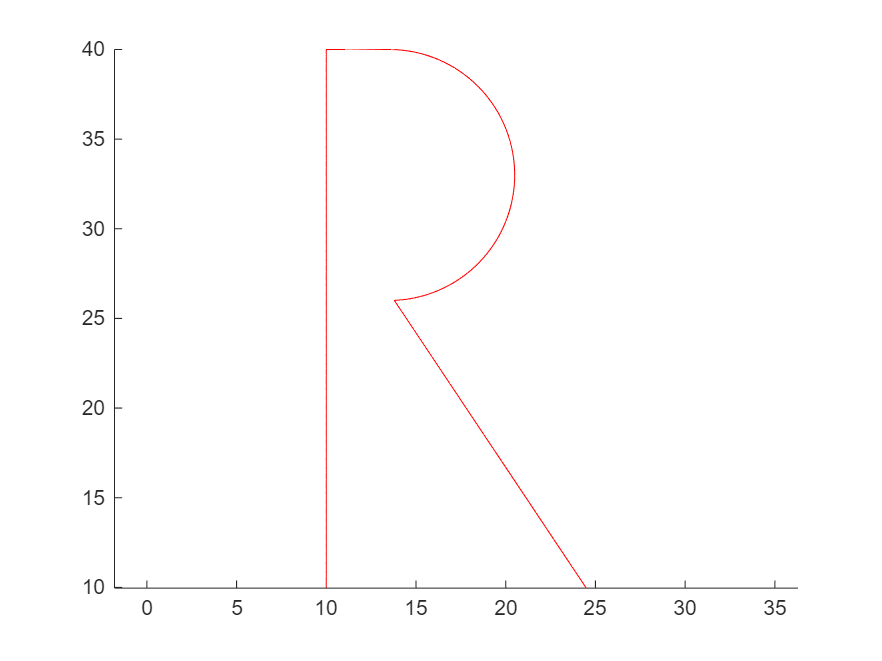


while path_posY < 40
    path_posY = path_posY + dt;
    positionX = [positionX, path_posX];
    positionY = [positionY, path_posY];

    time = time + dt;
    timelist = [timelist, time];
end

for theta = pi/2:-dtheta:-pi/2
    path_posX = loopC_X + loop_r*cos(theta);
    path_posY = loopC_Y + loop_radius*sin(theta);

    positionX = [positionX, path_posX];
    positionY = [positionY, path_posY];

    time = time + dt;
    timelist = [timelist, time];
end

while path_posY > 10
    path_posX = path_posX + dt;
    path_posY = path_posY - 1.5*dt;
    positionX = [positionX, path_posX];
    positionY = [positionY, path_posY];
    
    time = time + dt;
    timelist = [timelist, time];
end

figure
hold on
axis equal
plot(positionX, positionY, 'r')
hold off